## **LOAD POINT CLOUD DATA**

%data load
pointcloud = fopen('000564.bin','rb');
dataRaw = fread(pointcloud,'float32');
fclose(pointcloud);

dataRaw

dataRaw =    55.0460
    3.4020
    2.0740
         0
   55.0650
    3.5770
    2.0750
    0.0700
   55.0750
    3.7510


% | x |
% | y |
% | z |
% | r |
% ... Row = numPoint x 4 

%number of the point
[num,~] = size(dataRaw);
numPoint = num/4;

%reshape the data 
points = zeros(numPoint,4);

for i = 1:numPoint
    for j = 1:4
        points(i,j) = dataRaw(4*(i-1) + j, 1);
    end
end

points

points =    55.0460    3.4020    2.0740         0
   55.0650    3.5770    2.0750    0.0700
   55.0750    3.7510    2.0760    0.0900
   55.0890    3.9260    2.0770    0.1700
   55.1140    4.1020    2.0780    0.2700
   55.1180    4.1890    2.0780    0.2300
   55.1160    4.3640    2.0790         0
   55.1160    4.5380    2.0790         0
   64.5160   13.3970    2.4370         0
   77.5190   16.6110    2.8900         0


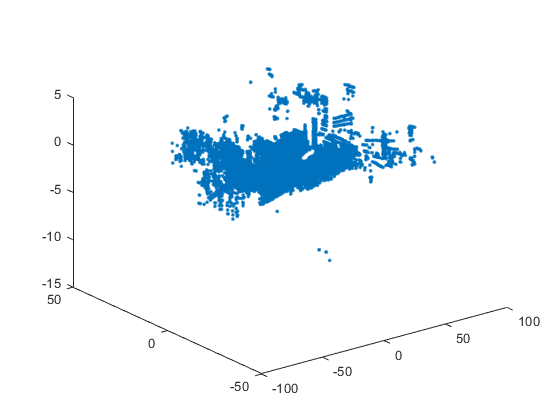

%| 1 | 2 | 3 | 4 |
%| x | y | z | r | float32
% ... numRow = numPoint

plot3(points(:,1),points(:,2),points(:,3),".");

## VOXEL GENERATE

### Input Arguments

% Points Arguments
points;                                  % [:, *4], float32; *x, y, z, r
                                         % input points
[num_Points,num_Attributes] = size(points);          
num_Points = cast(num_Points, "int32")   % int32

num_Points = int32
125104

                                         % number of input points,
num_Attributes = int32(num_Attributes)   % int32

num_Attributes = int32
4

                                         % number of attributes of points,
Ndims = num_Attributes - 1               % number of dimensions in space to represent points

Ndims = int32
3


% Environment Arguments
points_range = [0, -40, -3, 70.4, 40, 1] % [*4], float32, *x_min, y_min, z_min, x_max, y_max, z_max

points_range =          0  -40.0000   -3.0000   70.4000   40.0000    1.0000


                                         % pre-set range of points cloud

% Voxel Arguments 
voxel_size = [0.4, 0.2, 0.2]             % [*3], float; *x, y, z or * v_D, v_W, v_H

voxel_size =     0.4000    0.2000    0.2000


                                         % pre-set size of voxel 
grid_size = (points_range(4:6) - points_range(1:3) )./ voxel_size;
grid_size = cast(grid_size,'int32')      % [*3], int32; *x, y, z

grid_size = 1×3 int32 row vector
   176   400    20


                                         % grid size based on point cloud range and voxel size
maxNum_Points = int32(35)                % int32

maxNum_Points = int32
35

                                         % max number of points per voxel
maxNum_Voxel = int32(20000)              % int32 

maxNum_Voxel = int32
20000

                                         % max number of voxels
coor_to_voxelidx = -ones(grid_size,'int32');
                                         % [gride_size] or [x, y, z], int32
                                         % point dense map based on voxel grid coordinates
coors_VoxelinOrder = zeros(maxNum_Voxel, Ndims, 'int32');  
                                         % [maxNum_Voxel, *3], int32, *x, y, z
                                         % voxel index array to save the coordinates of voxels grid in order
num_Points_per_Voxel = zeros(maxNum_Voxel, 'int32');
                                         % [maxNum_Voxel], int32
                                         % points per voxel array
voxels = zeros(maxNum_Voxel, maxNum_Points, num_Attributes);
                                         % [maxNum_Voxel, maxNum_Points, num_Attributes], float32
                                         % voxels with points data in it 

### Algorithm

voxelidx = int32(0);        % buffer the array index of voxel  
num_Voxel = int32(0);       % voxel number
coor = zeros(1,3,'int32');  % buffer the grid coordinate for voxel
failed = false;             % state of points is in range or not
% Go through every points in the tensor
for i = 1 : num_Points
    failed = false;
    % Check if the point in the point range by go through every dimension of point (x,y,z)
    % if not in the range, skip (use continue) the functions/interation of this point, go to the interation of next point 
    for j = 1: Ndims
        c = floor((points(i,j) - points_range(j)) / voxel_size(j) );
        if ( c < 0 || c >= grid_size(j))
            failed = true;
            break;
        end
        % coor(Ndims - j + 1) = c;
        coor(j) = c;
    end
    if(failed)
        continue;
    end
    
    % mapping the point to the corresponding voxel
    voxelidx = coor_to_voxelidx(coor(1)+1, coor(2)+1, coor(3)+1);
    % if the voxel do not exist, generate a new one, update the voxel dense map and voxel index array
    if (voxelidx == -1)
        if (num_Voxel == 0)
            voxelidx = num_Voxel + 1;           
        else 
            voxelidx = num_Voxel;
        end
        if (num_Voxel > maxNum_Voxel)
            continue
        end
        num_Voxel = num_Voxel + 1;
        coor_to_voxelidx(coor(1)+1, coor(2)+1, coor(3)+1) = voxelidx;
        for k = 1: Ndims
            coors_VoxelinOrder(voxelidx, k) = coor(k);
        end
    end
    % else if the voxel have exist
    points_per_voxel = num_Points_per_Voxel(voxelidx);
    if (points_per_voxel < maxNum_Points)
        % voxel_point_mask_rw(voxelidx, num) = DType(1);
        for k = 1: num_Attributes
            voxels(voxelidx, points_per_voxel+1, k) = points(i, k);
        end
        num_Points_per_Voxel(voxelidx) = num_Points_per_Voxel(voxelidx) + 1;
    end
end
num_Voxel

num_Voxel = int32
9796

coors_VoxelinOrder

coors_VoxelinOrder = 20000×3 int32 matrix
    39   248    19
    39   249    19
    37   247    19
    36   247    19
    36   248    19
    36   249    19
    36   250    19
    23   244    18
    23   243    18
    22   243    18


num_Points_per_Voxel(1:60)

ans = 1×60 int32 row vector
    5    2    1    1    3    3    2    2    1    4    7    8    2    7    1   11    4    1    8    9   22    8    4   25   28    2   30    3    9   26    1   33    9    5    5    2    2    1    5    1    4   17   35   35   35    4   21   32   27   14


voxels(1,:,:)

ans = ans(:,:,1) =

   16.5370   16.5250   15.6610   15.6190   15.6150         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


ans(:,:,2) =

    9.8060    9.8690    9.6550    9.6960    9.7620         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


ans(:,:,3) =

    0.8590    0.8600    0.8310    0.8310    0.8320         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0      